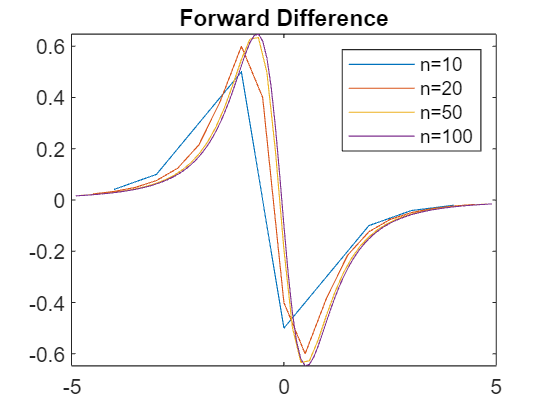


a = -5;
b= 5;
f=@(x)1./(1+x.^2);

n = 10;
x = a:(b-a)/n:b;
fd = forward_difference(f,a,b,n);
plot(x(2:end-1),fd)
hold on
n = 20;
x = a:(b-a)/n:b;
fd = forward_difference(f,a,b,n);
plot(x(2:end-1),fd)
n = 50;
x = a:(b-a)/n:b;
fd = forward_difference(f,a,b,n);
plot(x(2:end-1),fd)
n = 100;
x = a:(b-a)/n:b;
fd = forward_difference(f,a,b,n);
plot(x(2:end-1),fd)
legend('n=10', 'n=20', 'n=50', 'n=100')
title('Forward Difference')
hold off

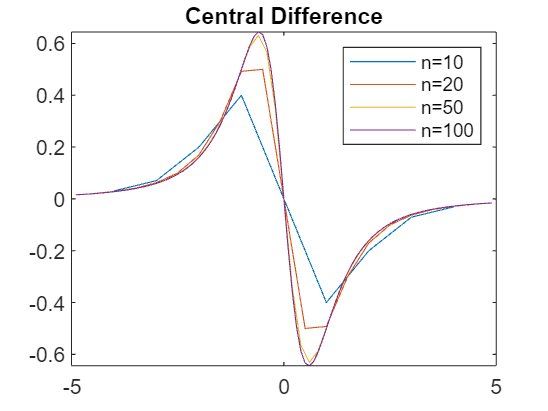


n = 10 ;
x = a:(b-a)/n:b;
cd = central_difference(f,a,b,n);
plot(x(2:end-1),cd)
hold on
n = 20 ;
x = a:(b-a)/n:b;
cd = central_difference(f,a,b,n);
plot(x(2:end-1),cd)
n = 50 ;
x = a:(b-a)/n:b;
cd = central_difference(f,a,b,n);
plot(x(2:end-1),cd)
n = 100 ;
x = a:(b-a)/n:b;
cd = central_difference(f,a,b,n);
plot(x(2:end-1),cd)
legend('n=10', 'n=20', 'n=50', 'n=100')
title('Central Difference')
hold off

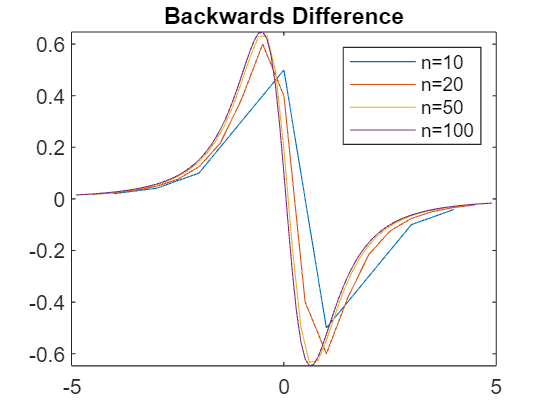


n = 10;
x = a:(b-a)/n:b;
bd = backward_difference(f,a,b,n);
plot(x(2:end-1),bd)
hold on
n = 20;
x = a:(b-a)/n:b;
bd = backward_difference(f,a,b,n);
plot(x(2:end-1),bd)
n = 50;
x = a:(b-a)/n:b;
bd = backward_difference(f,a,b,n);
plot(x(2:end-1),bd)
n = 100;
x = a:(b-a)/n:b;
bd = backward_difference(f,a,b,n);
plot(x(2:end-1),bd)
title("Backwards Difference")
legend("n=10", 'n=20', 'n=50', 'n=100')

hold off

2.

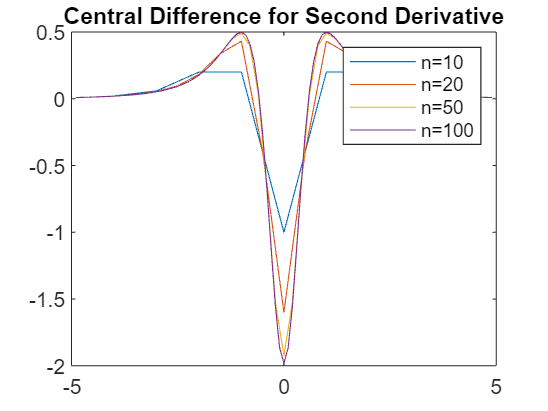

n=10;
x=a:(b-a)/n:b;
f_prime2=central_difference2(f,a,b,n);
plot(x(2:end-1),f_prime2)
hold on 
n=20;
x=a:(b-a)/n:b;
f_prime2=central_difference2(f,a,b,n);
plot(x(2:end-1),f_prime2)
n=50;
x=a:(b-a)/n:b;
f_prime2=central_difference2(f,a,b,n);
plot(x(2:end-1),f_prime2)
n=100;
x=a:(b-a)/n:b;
f_prime2=central_difference2(f,a,b,n);
plot(x(2:end-1),f_prime2)
hold off
legend('n=10','n=20','n=50','n=100')
title('Central Difference for Second Derivative')

3.

N = [1,2,5,10,20,40];
F0=f(0)*ones(1,length(N));
dnf=(f(10.^(-N))-F0)./(10.^(-N))

dnf =    -0.0990   -0.0100   -0.0000         0         0         0


The approximation for x = 0 for the derivative of f converges to 0 as N increases. This makes sense because each derivative of f gets closer and closer to 0

Functions

function [f_prime] = forward_difference(f,a,b,n)
h=(b-a)/n;
x=a:h:b;
F=f(x);
f_prime = (F(3:end) - F(2:end-1))/h;
end
function [f_prime] = backward_difference(f,a,b,n)
h=(b-a)/n;
x=a:h:b;
F=f(x);
f_prime = (F(1:end-2) - F(2:end-1))/-h;
end
function [f_prime] = central_difference(f,a,b,n)
h=(b-a)/n;
x=a:h:b;
F=f(x);
f_prime = (F(3:end)-F(1:end-2))/(2*h);
end
function [f_prime2] = central_difference2(f,a,b,n)
h=(b-a)/n;
x=a:h:b;
F=f(x);
f_prime2=(1/h^2)*(F(1:end-2)-2*F(2:end-1)+F(3:end));
end